% Util Functions
addpath(genpath('.\My5300Tools'));
addpath(genpath('.\Basic5300Tools'));
addpath(genpath(".\spotfimusicaoaestimation"));

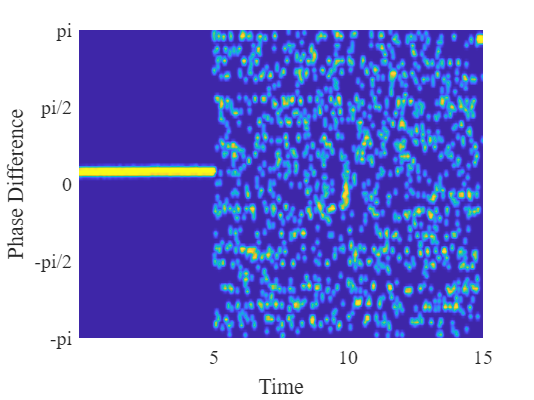

% Figure 13(a): Obfuscate Phase Difference
test_angles = 0:0;
oxs = ["", "_ox"];
subcarrier_id = 15;

% Calculate Phase Offset for Calibration
file_pre = ".\Data\AoAEstimation\calibration\data2_";
filePath = file_pre+"12";
P1 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
filePath = file_pre+"21";
P2 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
c21 = (P2 + P1)/2;
d21 = c21(:,1);
d21 = d21';

for data_index = 1:1:length(test_angles)
    ang = test_angles(data_index);
    
    noOx_range = 1:1:1000;
    Ox_range = 1:1:2000;

    ox = oxs(1); % Without Obfuscation
    file_path = ".\Data\AoAEstimation\still_test\"+ang+ox+"_2";
    phase_noOx = GetPhaseDifByAntennaSeqWithCalibration(file_path, [1,2], d21);
    phase_noOx = phase_noOx(subcarrier_id, noOx_range);

    ox = oxs(2); % With Obfuscation
    file_path = ".\Data\AoAEstimation\still_test\"+ang+ox+"_2";
    phase_Ox = GetPhaseDifByAntennaSeqWithCalibration(file_path, [1,2], d21);
    phase_Ox = phase_Ox(subcarrier_id, Ox_range);

    phase_ = [phase_noOx, phase_Ox];
    phase_ = phase_';
    N = size(phase_, 1);

    % heatmap
    N_grid = 100;
    Y_range = pi; % [-Y_range, Y_range]
    [X,Y] = meshgrid(1:N, -Y_range:2*Y_range/N_grid:Y_range);
    Z = zeros(size(X));
    Zsum = Z;
    for j=1:length(phase_)
        sigma_x = 15;
        sigma_y = 0.05;
        Z=Gauss2D(X,Y,sigma_x,sigma_y,j,phase_(j));
        Zsum=Heatsum(Zsum,Z);
    end
    figure('Name',ang+ox+"1.mat",'NumberTitle','off')
    pcolor(X,Y,Zsum);shading interp
    xlabel("Time");
    ylabel("Phase Difference");
    set(gca,'XTick',0:1000:4000);
    set(gca,'XTicklabel',{'0','5','10','15'})
    set(gca,'YTick',-2*pi:pi/2:2*pi);
    set(gca,'YTicklabel',{'-2pi','-3pi/2','-pi','-pi/2','0','pi/2','pi','3pi/2','2pi'})
    set(gca,'FontName','Times New Roman','FontSize',12)
    axis([1 N -Y_range Y_range]);
end

% SpotFi: AoA Estimation
test_angles = 0:0;
oxs = ["", "_ox"];

% Calculate Phase Offset for Calibration
file_pre = ".\Data\AoAEstimation\calibration\data2_";
filePath = file_pre+"12";
P1 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
filePath = file_pre+"21";
P2 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
c21 = (P2 + P1)/2;
d21 = c21(:,1);
d21 = d21';

for data_index = 1:1:length(test_angles)
    for ox_i = 1:length(oxs)
        ang = test_angles(data_index);
        ox = oxs(ox_i);
        file_path = ".\Data\AoAEstimation\still_test\"+ang+ox+"_2";
        csi_trace = readfile(file_path);

        Ntx = csi_trace{1}.Ntx; % Number of tx antennas
        Nrx = csi_trace{1}.Nrx; % Number of rx antennas
        Npacket = length(csi_trace);
        Nresults = 1; % Top n SpotFi results
        distance = 3; % cm Actual antenna distance
        theta = zeros(Ntx, Npacket, Nresults);

        % % 5G
        fc = 5.320e9; % center frequency
        M = 2;%Nrx;    % number of rx antennas
        fs = 40e6; % channel bandwidth
        c = 3e8;  % speed of light
        d = distance*0.01; % m  % distance between adjacent antennas in the linear antenna array
        SubCarrInd = [-58,-54,-50,-46,-42,-38,-34,-30,-26,-22,-18,-14,-10,-6,-2,2,6,10,14,18,22,26,30,34,38,42,46,50,54,58]; % WiFi subcarrier indices at which CSI is available
        N = length(SubCarrInd); % number of subcarriers
        fgap = fs/128;
        lambda = c/fc;  % wavelength
        T = 1; % number of transmitter antennas

        % MUSIC algorithm requires estimating MUSIC spectrum in a grid. paramRange captures parameters for this grid
        % For the following example, MUSIC spectrum is caluclated for 101 ToF (Time of flight) values spaced equally between -25 ns and 25 ns. MUSIC spectrum is calculated for for 101 AoA (Angle of Arrival) values between -90 and 90 degrees.
        paramRange = struct;
        paramRange.GridPts = [101 101 1]; % number of grid points in the format [number of grid points for ToF (Time of flight), number of grid points for angle of arrival (AoA), 1]
        paramRange.delayRange = [-100 100]*1e-9; % lowest and highest values to consider for ToF grid. 1~0.3m
        paramRange.angleRange = 90*[-1 1]; % lowest and values to consider for AoA grid.
        do_second_iter = 0;
        % paramRange.seconditerGridPts = [1 51 21 21];
        paramRange.K = floor(M/2)+1; % parameter related to smoothing.  
        paramRange.L = floor(N/2); % parameter related to smoothing.  
        paramRange.T = 1;
        paramRange.deltaRange = [0 0]; 

        maxRapIters = Inf;
        useNoise = 0;
        paramRange.generateAtot = 2;

        delayRange = paramRange.delayRange;
        deltaRange = paramRange.deltaRange;
        angleRange = paramRange.angleRange;
        GridPts = paramRange.GridPts;
        MaxAngle = angleRange(2);
        MinAngle = angleRange(1);
        [aTot,GridStart,GridSpacing, delayGridValue, u_sGridValue, deltaGridValue] = gridVecBackscatter(deltaRange, M, T, d, fc, c, do_second_iter, delayRange, SubCarrInd, N, fgap, GridPts, MaxAngle, MinAngle, paramRange.generateAtot);

        parfor index=1:2000
            csi_entry = csi_trace{index};
            csi_tmp = get_scaled_csi(csi_entry);

            tmp_theta = zeros(Ntx, Nresults);
            tmp_dis = zeros(Ntx, Nresults);
            for tx_index = 1:1:Ntx
                % Only consider measurements for transmitting on one antenna
                csi = csi_tmp(tx_index, :, :);
                % Remove the single element dimension
                csi = squeeze(csi);
                csi = csi(1:M,:);

                % Calibration
                csi(2,:) = abs(csi(2,:)).*cos(angle(csi(2,:))+d21)+1i*abs(csi(2,:)).*sin(angle(csi(2,:))+d21);

                csi = csi';
                sample_csi_trace = csi(:);
                % sample CSI trace is a 90x1 vector where first 30 elements correspond to subcarriers for first rx antenna, second 30 correspond to CSI from next 30 subcarriers and so on.
                % replace sample_csi_trace with CSI from Intel 5300 converted to 90x1 vector

                % ToF sanitization code (Algorithm 1 in SpotFi paper)
                csi_plot = reshape(sample_csi_trace, N, M);
                [PhsSlope, PhsCons] = removePhsSlope(csi_plot,M,SubCarrInd,N);
                ToMult = exp(1i* (-PhsSlope*repmat(SubCarrInd(:),1,M) - PhsCons*ones(N,M) ));
                csi_plot = csi_plot.*ToMult;
                relChannel_noSlope = reshape(csi_plot, N, M, T);
                sample_csi_trace_sanitized = relChannel_noSlope(:);

                % MUSIC algorithm for estimating angle of arrival
                % aoaEstimateMatrix is (nComps x 5) matrix where nComps is the number of paths in the environment. First column is ToF in ns and second column is AoA in degrees as defined in SpotFi paper
                aoaEstimateMatrix = backscatterEstimationMusicFast(aTot,GridStart,GridSpacing, delayGridValue, u_sGridValue, deltaGridValue,sample_csi_trace_sanitized, M, N, c, fc,...
                                    T, fgap, SubCarrInd, d, paramRange, maxRapIters, useNoise, do_second_iter, ones(Nresults))
                tofEstimate = aoaEstimateMatrix(:,1); % ToF in nanoseconds
                aoaEstomate = aoaEstimateMatrix(:,2); % AoA in degrees
                
                % Record AoA results
                tmp = zeros(Nresults-length(aoaEstomate), 1);
                aoaEstomate = [aoaEstomate; tmp];
                tmp_theta(tx_index, :) = aoaEstomate;

                theta(tx_index,index, :) = tmp_theta(tx_index, :);
            end
        end
        savePath = ['.\Data\AoAEstimation\still_test\Top', num2str(Nresults), '\', num2str(ang), num2str(ox), '_2.mat'];
        save(savePath, 'theta');
    end
end

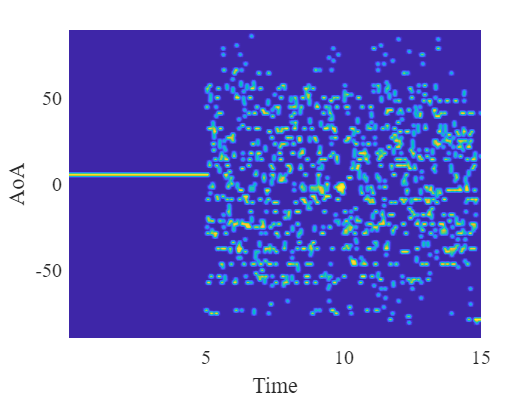

% Figure 13(b): Obfuscate AoA Estimation
test_angles = 0:0;
oxs = ["", "_ox"];

for data_index = 1:1:length(test_angles)
    ang = test_angles(data_index);
    ox = oxs(1);
    noOx_range = 1:1:1000;
    Ox_range = 1:1:2000;
    file_path = ".\Data\AoAEstimation\still_test\Top1\"+ang+ox+"_2.mat";
    a = load(file_path);
    theta_noOx = a.theta(1, noOx_range);
    ox = oxs(2);
    file_path = ".\Data\AoAEstimation\still_test\Top1\"+ang+ox+"_2.mat";
    a = load(file_path);
    theta_Ox = a.theta(1, Ox_range);
    theta_ = [theta_noOx, theta_Ox];
    theta_ = theta_';
    N = size(theta_, 1);
    
    % heatmap
    N_grid = 100;
    Y_range = 90; % [-Y_range, Y_range]
    [X,Y] = meshgrid(1:N, -Y_range:2*Y_range/N_grid:Y_range);
    Z = zeros(size(X));
    Zsum = Z;
    for j=1:length(theta_)
        sigma_x = 15;
        sigma_y = 0.4;
        Z=Gauss2D(X,Y,sigma_x,sigma_y,j,theta_(j));
        Zsum=Heatsum(Zsum,Z);
    end
    figure('Name',ang+ox+"_2.mat",'NumberTitle','off')
    pcolor(X,Y,Zsum);shading interp
    xlabel("Time");
    ylabel("AoA");
    set(gca,'XTick',0:1000:3000);
    set(gca,'XTicklabel',{'0','5','10','15'})
    set(gca,'FontName','Times New Roman','FontSize',12)
    axis([1 N -Y_range Y_range]);
end

function Z=Gauss2D(X,Y,sigma_x, sigma_y,a,b)
    Z=0.5*exp(-((X-a).^2./sigma_x.^2+(Y-b).^2./sigma_y.^2));
end

function B=Heatsum(A1,A2)
B=1-(1-A1).*(1-A2);
end
